clear;

data = readtable("data.xlsx");

DCData = readtable("OnlineData\Commercial-Office.csv");

loadShedding = readtable("LoadsheddingDetailed.xlsx")%readtable("OnlineData\LoadSheddingHistory.xlsx");

loadShedding = 4327×5 table
       Date          Time         Stage          Area        DurationMin
    ___________    ________    ___________    ___________    ___________

    02-Feb-2022         0.5    {'Stage 1'}    {'Area 3' }      {'130'}  
    02-Feb-2022     0.58333    {'Stage 1'}    {'Area 4' }      {'130'}  
    02-Feb-2022     0.66667    {'Stage 1'}    {'Area 5' }      {'133'}  
    02-Feb-2022        0.75    {'Stage 1'}    {'Area 6' }      {'135'}  
    02-Feb-2022     0.83333    {'Stage 1'}    {'Area 7' }      {'160'}  
    02-Feb-2022     0.91667    {'Stage 2'}    {'Area 8' }      {'120'}  
    02-Feb-2022     0.91667    {'Stage 2'}    {'Area 16'}      {'120'}  
    03-Feb-2022           0    {'Stage 2'}    {'Area 1' }      {'140'}  
    03-Feb-2022           0    {'Stage 2'}    {'Area 9' }      {'140'} 


new_loadshedding = readtable("")

Area15Idx = (loadShedding.Area == "Area 15");

loadShedding = loadShedding(Area15Idx,:)

loadShedding = 269×5 table
       Date          Time         Stage          Area        DurationMin
    ___________    ________    ___________    ___________    ___________

    03-Feb-2022         0.5    {'Stage 1'}    {'Area 15'}      {'128'}  
    04-Feb-2022     0.16667    {'Stage 2'}    {'Area 15'}      {'134'}  
    04-Feb-2022     0.83333    {'Stage 1'}    {'Area 15'}      {'139'}  
    06-Feb-2022    0.083333    {'Stage 1'}    {'Area 15'}      {'130'}  
    08-Feb-2022    0.083333    {'Stage 2'}    {'Area 15'}      {'135'}  
    08-Mar-2022    0.083333    {'Stage 2'}    {'Area 15'}      {'137'}  
    08-Mar-2022        0.75    {'Stage 1'}    {'Area 15'}      {'130'}  
    10-Mar-2022           0    {'Stage 4'}    {'Area 15'}      {'150'}  
    10-Mar-2022     0.33333    {'Stage 3'}    {'Area 15'}      {'150'}  






% Join tables
data = outerjoin(data,loadShedding,"Type","left","LeftKeys",["date",...
    "time"],"RightKeys",["Date","Time"])

data = 8760×30 table
    meter_serial            meter_desc                   tstamp              date            day           time          tou         week_number            impwh             difference_imp_kwh     ptot      stot     expwh    difference_exp_kwh    pftot      md       qtot      epoch_timestamp        interval_start       waste    meter_id    tou_id    season_profile_id    season_class_id    tariff_id    Date    Time      Stage          Area       DurationMin
    

str2num(cell2mat(data.DurationMin(805)))

ans = '128'


for i = 1:size(data.Area(:))
    if data.Area(i) ~= "Area 15"
        data.LoadShedding(i) = 0;
    else 
        duration = floor(str2num(cell2mat(data.DurationMin(i)))/60);
        for j = 0:duration
            data.LoadShedding(i+j) =1;
        end
    end
end


summary(data)

Variables:

    meter_serial: 8760×1 double

        Values:

            Min       1.8132e+07
            Median    1.8132e+07
            Max       1.8132e+07

    meter_desc: 8760×1 cell array of character vectors

    tstamp: 8760×1 datetime

        Values:

            Min       01-Jan-2022 00:00:00
            Median    02-Jul-2022 11:30:00
            Max       31-Dec-2022 23:00:00

    date: 8760×1 datetime

        Values:

            Min       01-Jan-2022
            Median    02-Jul-2022
            Max       31-Dec-2022

    day: 8760×1 cell array of character vectors

    time: 8760×1 double

        Values:

            Min             0 
            Median    0.47917 
            Max       0.95833 

    tou: 8760×1 cell array of character vectors

    week_number: 8760×1 double

        Values:

            Min           1   
         

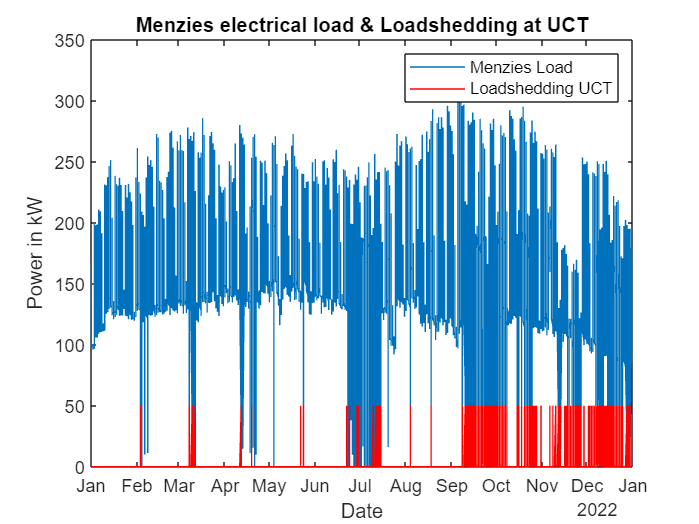


ActiveShedding = data.LoadShedding(:);
plot(data.date, data.ptot)
hold on
plot(data.date,ActiveShedding*50, "r")
hold off
legend("Menzies Load","Loadshedding UCT");
title("Menzies electrical load & Loadshedding at UCT")
xlabel("Date")
ylabel("Power in kW")


data.activeShedding = ~(ActiveShedding);


writetable(data(:,'LoadShedding'), "loadShedding2022.csv");